Loads and processes data (run everything from playground)

% fluo, MeanAP
set1 = load('../dat/3400b_7dT_set1/inference_traces_3400b_7dT_set1_dT7.mat', 'trace_struct_final');
%set1 = load('../dat/1900b_7dT_alt2/inference_traces_1500b_7dT_alt2_dT7.mat', 'trace_struct_final');
set1 = set1.trace_struct_final;
trace_struct1 = struct;
idx = 1;
for i = 1:length(set1)
    if length(set1(i).fluo_interp) > 30 && ...
            length(set1(i).cp_frames) / ...
            length(set1(i).all_frames) > 0
        trace_struct1(idx).fluo = set1(i).fluo_interp;
        trace_struct1(idx).ap = (.40 - set1(i).MeanAP) * 100;
        idx = idx + 1;
    end
end
% fluo_interp, MeanAP
set2 = load('../dat/2650b_7dT_alt/inference_traces_2250b_7dT_alt_dT7.mat', 'trace_struct_final');
%set2 = load('../dat/1900b_7dT_set2/inference_traces_1500b_7dT_set2_dT7.mat', 'trace_struct_final');
set2 = set2.trace_struct_final;
trace_struct2 = struct;
idx = 1;
for i = 1:length(set2)
    if length(set2(i).fluo_interp) > 30 && ...
            length(set2(i).cp_frames) / ...
            length(set2(i).all_frames) > 0
        trace_struct2(idx).fluo = set2(i).fluo_interp;
        trace_struct2(idx).ap = set2(i).MeanAP;
        idx = idx + 1;
    end
end

load('../dat/compiled_data/1900compiled.mat');
load('../dat/compiled_data/2650compiled.mat');
load('../dat/compiled_data/3400compiled.mat');

Compiles data sets (enforcing constraints on trace length and minimum number of points registered)

% compiles 1.9kb traces

len1900_set1 = load('../dat/1900b_7dT_alt2/inference_traces_1500b_7dT_alt2_dT7.mat', 'trace_struct_final');
len1900_set1 = len1900_set1.trace_struct_final;
len1900_set2 = load('../dat/1900b_7dT_set2/inference_traces_1500b_7dT_set2_dT7.mat', 'trace_struct_final');
len1900_set2 = len1900_set2.trace_struct_final;
all1900 = [len1900_set1 len1900_set2];
final1900 = struct;
idx = 1;
for entry = all1900
    if length(entry.cp_frames) > 30
        final1900(idx).fluo = entry.fluo_interp;
        final1900(idx).ap = entry.MeanAP;
        idx = idx + 1;
    end
end

save('../dat/compiled_data/1900compiled.mat', 'final1900');

len2650_set1 = load('../dat/2650b_7dT_alt/inference_traces_2250b_7dT_alt_dT7.mat', 'trace_struct_final');
len2650_set1 = len2650_set1.trace_struct_final;
len2650_set2 = load('../dat/2650b_7dT_set2/inference_traces_2250b_7dT_set2_dT7.mat', 'trace_struct_final');
len2650_set2 = len2650_set2.trace_struct_final;
all2650 = [len2650_set1 len2650_set2];
final2650 = struct;
idx = 1;
for entry = all2650
    if length(entry.cp_frames) > 30
        final2650(idx).fluo = entry.fluo_interp;
        final2650(idx).ap = entry.MeanAP;
        idx = idx + 1;
    end
end

save('../dat/compiled_data/2650compiled.mat', 'final2650');

len3400_set1 = load('../dat/3400b_7dT_set1/inference_traces_3400b_7dT_set1_dT7.mat', 'trace_struct_final');
len3400_set1 = len3400_set1.trace_struct_final;
all3400 = [len3400_set1];
final3400 = struct;
idx = 1;
for entry = all3400
    if length(entry.cp_frames) > 30
        final3400(idx).fluo = entry.fluo_interp;
        final3400(idx).ap = entry.MeanAP;
        idx = idx + 1;
    end
end

save('../dat/compiled_data/3400compiled.mat', 'final3400');

Looks at random traces

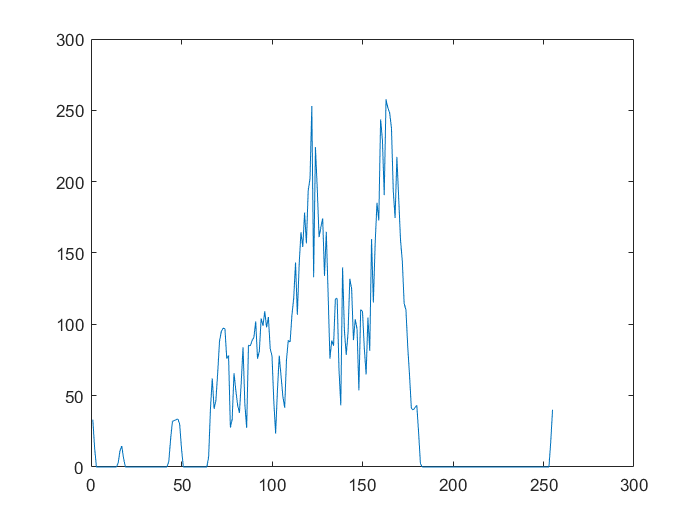

figure();
plot(trace_struct1(34).fluo);

Compare how many in between points each of them missed

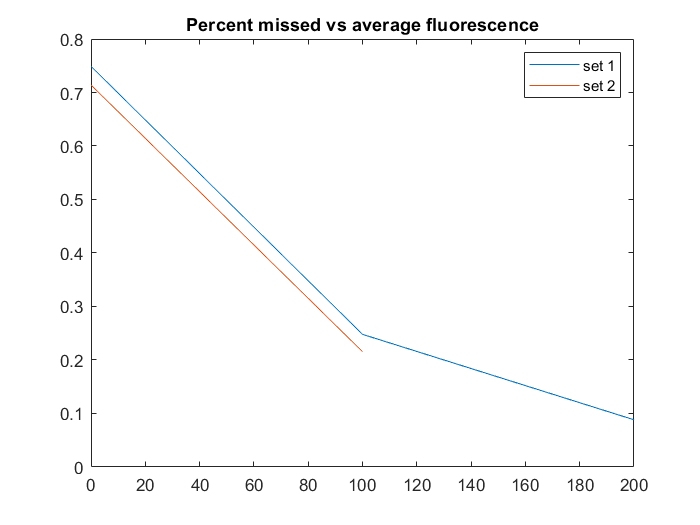

missed2250 = 0;
fluo2250 = 0:100:1200;
miss2250 = zeros(1, length(fluo2250));
counts2250 = zeros(1, length(fluo2250));
for i = 1:length(set1)
    all_len = length(set1(i).all_frames);
    meas_len = length(set1(i).cp_frames);
    missed2250 = missed2250 + (all_len - meas_len) / all_len;
    mean_val = mean(set1(i).fluo_interp);
    [val, idx] = min(abs(mean_val - fluo2250));
    miss2250(idx) = miss2250(idx) + (all_len - meas_len) / all_len;
    counts2250(idx) = counts2250(idx) + 1;
end
missed2250 = missed2250 / length(set1);
miss2250 = miss2250 ./ counts2250;

missed4700 = 0;
fluo4700 = 0:100:1200;
miss4700 = zeros(1, length(fluo4700));
counts4700 = zeros(1, length(fluo4700));
for j = 1:length(set2)
    all_len = length(set2(j).all_frames);
    meas_len = length(set2(j).cp_frames);
    missed4700 = missed4700 + (all_len - meas_len) / all_len;
    mean_val = mean(set2(j).fluo_interp);
    [val, idx] = min(abs(mean_val - fluo4700));
    miss4700(idx) = miss4700(idx) + (all_len - meas_len) / all_len;
    counts4700(idx) = counts4700(idx) + 1;
end
missed4700 = missed4700 / length(set2);
miss4700 = miss4700 ./ counts4700;

figure();
plot(fluo2250, miss2250);
hold on
plot(fluo4700, miss4700);
legend('set 1', 'set 2');
title('Percent missed vs average fluorescence');

Looks at fluorescence content

fluo_distrib2250 = []


fluo_distrib2250 =

     []



fluo_distrib4700 = []


fluo_distrib4700 =

     []



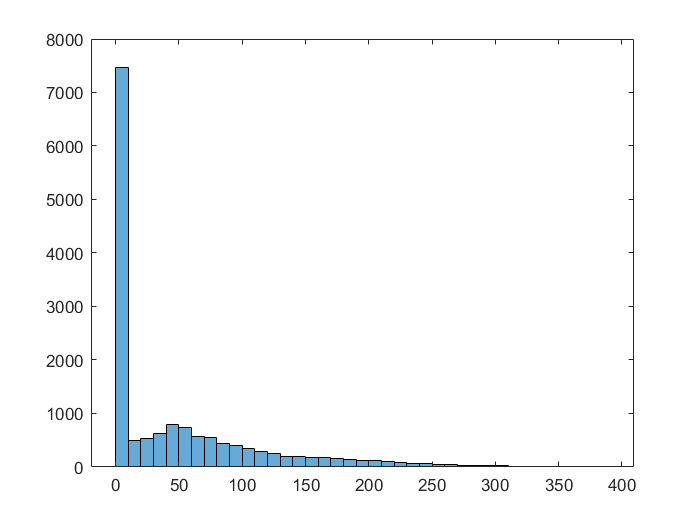


for i = 1:length(trace_struct1)
    fluo_distrib2250 = [fluo_distrib2250 trace_struct1(i).fluo];
end

figure();
title('Fluorescnece Distribution 2250bp');
histogram(fluo_distrib2250);

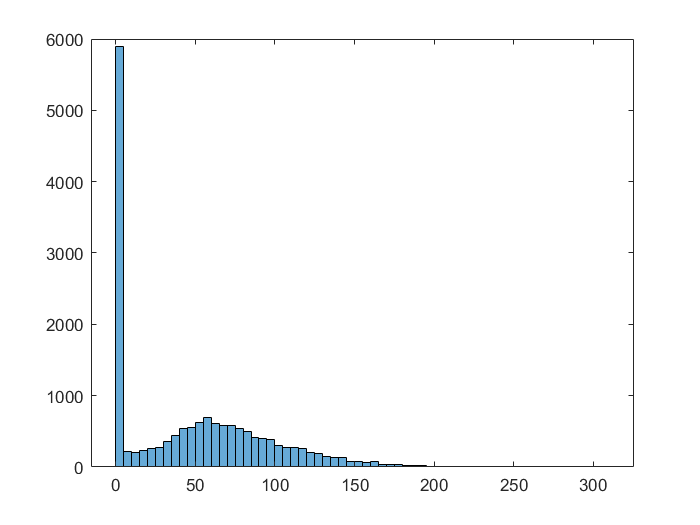


for j = 1:length(trace_struct2)
    fluo_distrib4700 = [fluo_distrib4700 trace_struct2(j).fluo];
end

figure();
title('Fluorescnece Distribtion 4700bp');
histogram(fluo_distrib4700);

display(mean(fluo_distrib4700(fluo_distrib4700 > 100)))

  129.7499



display(mean(fluo_distrib2250(fluo_distrib2250 > 100)))

  168.3730



Preps for autocorrelation and derivatives (and generates them) (run from src)

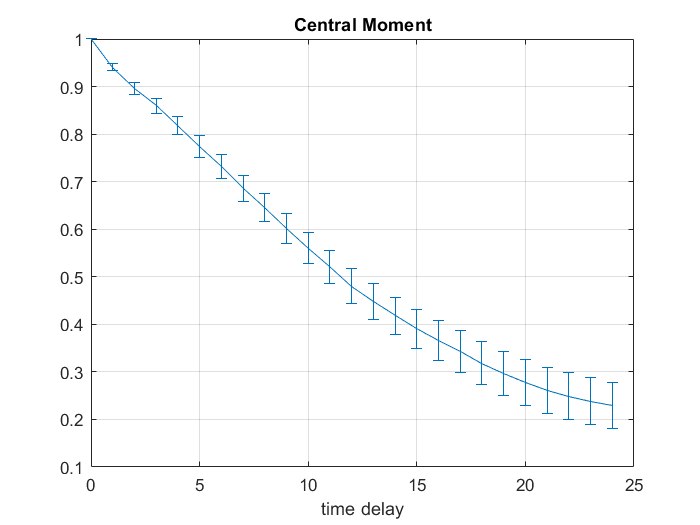

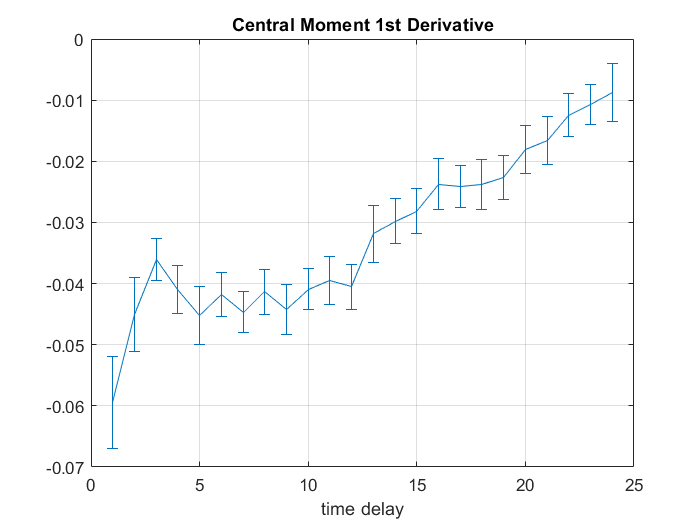

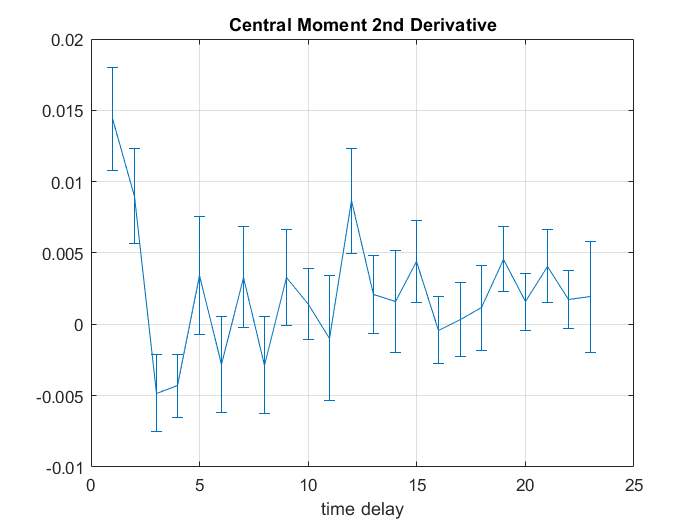

addpath('../')
trace_struct = [final3400];
traces = cell(1, length(trace_struct));
for i = 1:length(traces)
    traces{i} = smooth(trace_struct(i).fluo, 1)';
end
gen_auto_cor(traces, true, true, true, true, 25, 0);

Divides traces up into 36 long fragments (making sure that none of them are more than 1/3 zero). 12 points repeat ever time.

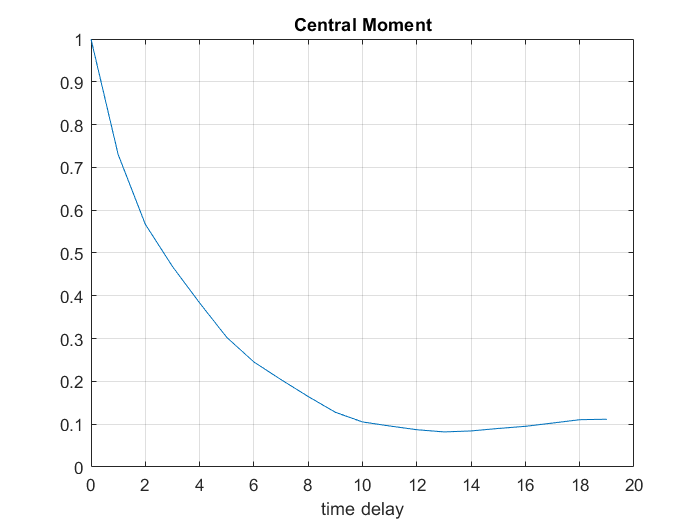

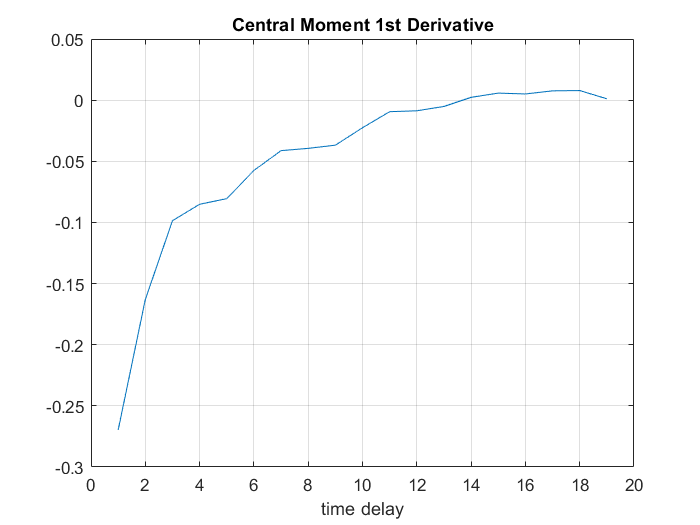

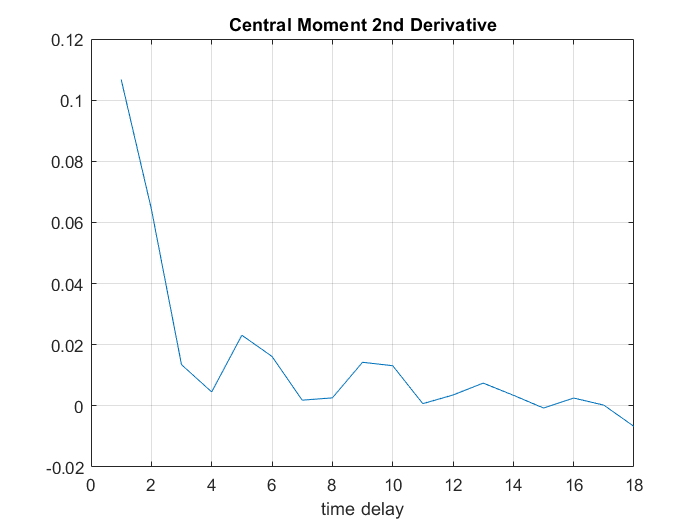

addpath('../');
trace_struct = [trace_struct1 trace_struct2];
traces = cell(1);
trace_len = 24;
num_nonzero = 22;
jump = 1;
idx = 1;
for i = 1:length(trace_struct)
    fluo = trace_struct(i).fluo;
    j = 1;
    while j + trace_len - 1 <= length(fluo)
        if nnz(fluo(j:j+trace_len-1)) > num_nonzero
            traces{idx} = fluo(j:j+trace_len-1);
            idx = idx + 1;
        end
        j = j + jump;
    end
end

gen_auto_cor(traces,true,true,true,false,20,0);

Downsamples traces

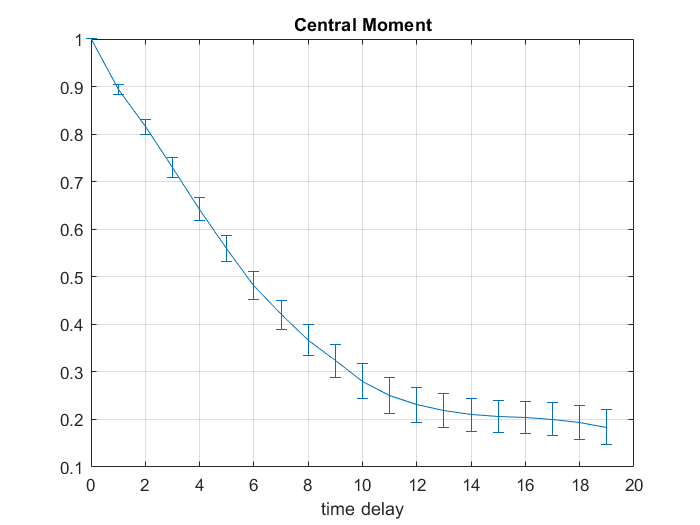

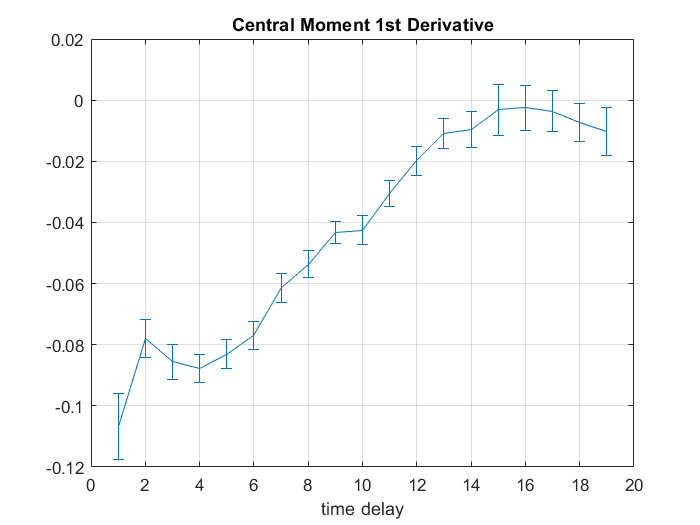

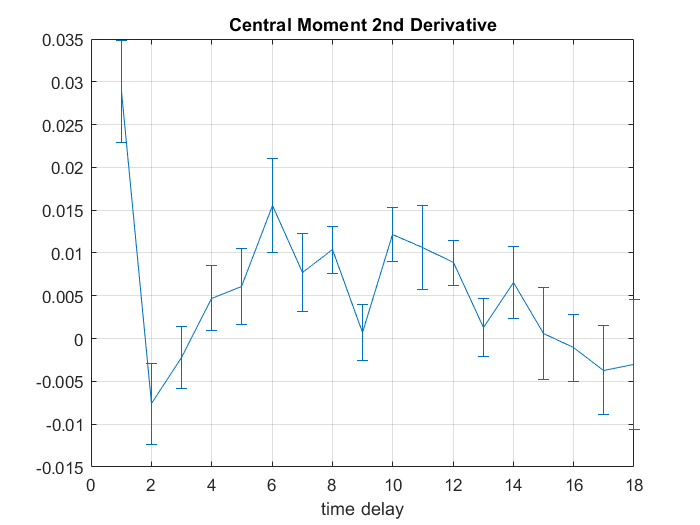

addpath('../');
trace_struct = [final3400];
traces = cell(1);
skip = 1;
idx = 1;
for i = 1:length(trace_struct)
    fluo = smooth(trace_struct(i).fluo,1)';
    for s = 1:skip + 1
        traces{idx} = fluo(skip:skip+1:end);
        idx = idx + 1;
    end
end

gen_auto_cor(traces,true,true,true,true,20,0);

Downsample selective traces

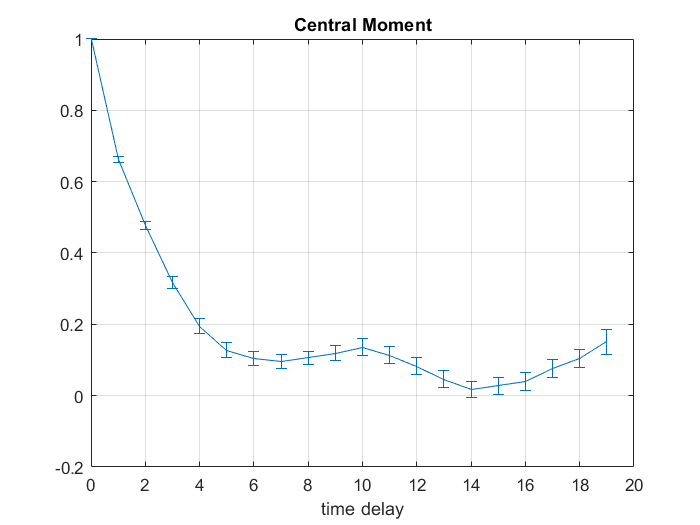

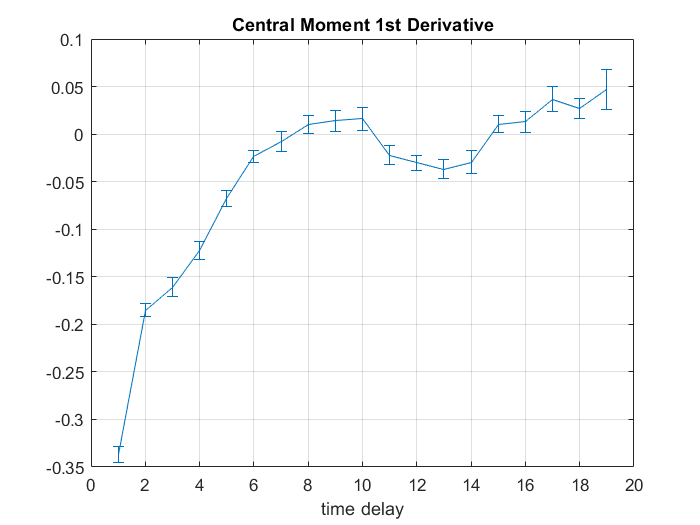

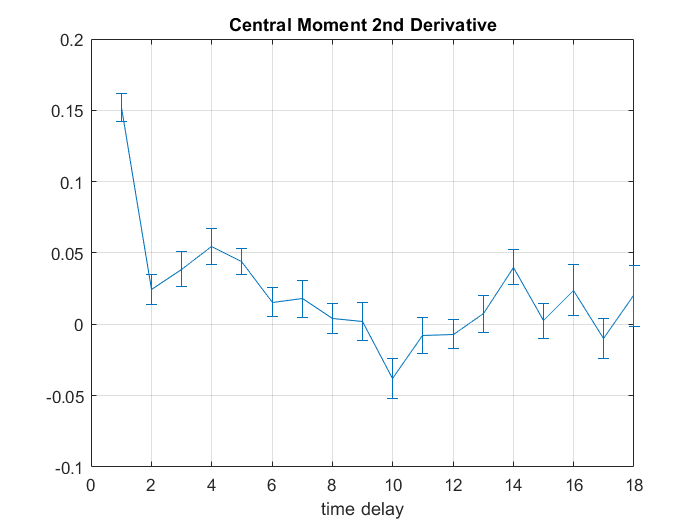

addpath('../');
trace_struct = [trace_struct1 trace_struct2];
traces = cell(1);
min_len = 60;
idx = 1;
for i = 1:length(trace_struct)
    fluo = trace_struct(i).fluo;
    j = 1;
    start = 1;
    while j <= length(fluo)
        if fluo(j) == 0
            if j - start >= min_len
                traces{idx} = fluo(start:j-1);
                idx = idx + 1;
            end
            start = j + 1;
        end
        j = j + 1;
    end
    if j - start >= min_len
        traces{idx} = fluo(start:j-1);
        idx = idx + 1;
    end
end

new_traces = cell(1);
skip = 2;
idx = 1;
for i = 1:length(traces)
    fluo = traces{i};
    for s = 1:skip + 1
        new_traces{idx} = fluo(skip:skip+1:end);
        idx = idx + 1;
    end
end

gen_auto_cor(new_traces,true,true,true,true,20,0);